anya = ayAnya(10413:11218);
chas = ayChase(11827:12626);
coli = ayColin(12906:13705);
cusa = ayCusai(7044:7844);
dieg = ayDiego(10016:10819);
jame = ayJames(17977:18779);
juli = ayJuul(6190:6995);
kawi = ayKawin(7232:8037);
nate = ayNathan(7729:8534);
rick = ayRicky(6577:7380);
length(rick)

ans = 804

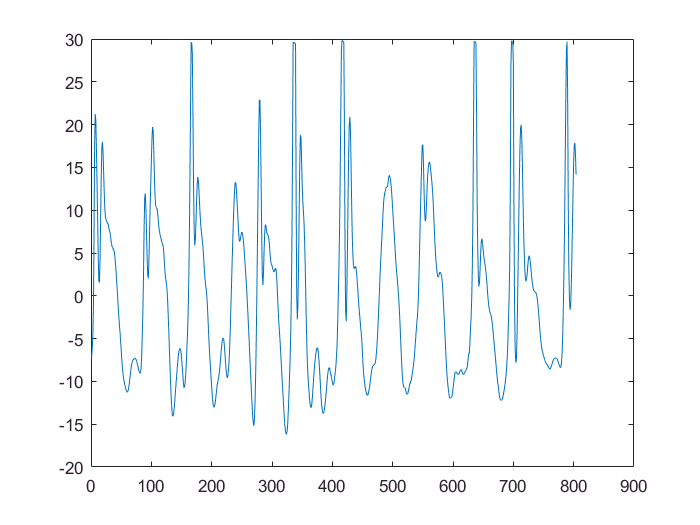

plot(rick)

P_anya = cell2mat(num2cell(reshape(anya, 62, 13), 1))

P_anya =    -4.3558    6.3608  -11.6308   -1.0894    4.2171  -14.7949  -10.0325   -6.7504  -16.4133  -20.9358  -13.9653  -12.3611   -9.3282
   -1.0414    7.5944  -11.2163    4.7528    7.9865  -14.7001   -4.8868   -5.3560  -16.6107  -21.0617  -15.2083  -13.8176  -10.7082
    2.2399    9.9657  -10.4550   13.7331   16.8505  -14.4107    0.7243   -3.6631  -16.6483  -20.9763  -15.9098  -15.2551  -12.2731
    8.5603   12.5591   -9.3422   20.9950   21.9025  -13.7622    7.4120   -1.0212  -16.6910  -20.9996  -16.2513  -16.5367  -13.9182
   15.1602   16.6455   -7.9497   24.1023   24.9059  -12.8943   23.6986    3.7185  -16.7050  -21.1480  -16.3857  -17.6093  -15.6270
   21.2713   19.9332   -6.1318   26.0730   26.4091  -11.6198   29.9646   13.6327  -16.2145  -20.3406  -16.4537  -18.4726  -17.4919
   27.6315   21.4309   -3.9671   29.2812   28.3658  -10.1068   29.9624   22.8132  -14.5979  -18.1732  -16.7088  -18.9194  -19.1442
   30.1716   20.6769   -1.3390   30.1114   29.4048   -8.3554   29.9430   2

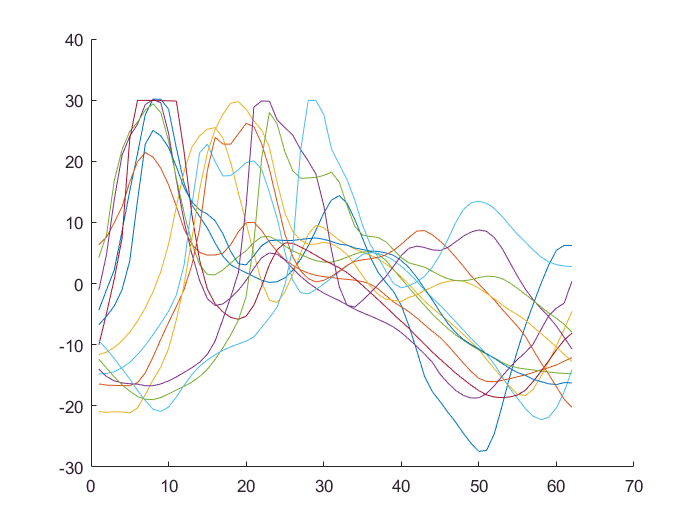

figure
hold on;
for k = 1:13
    plot(P_anya(:,k))
end
hold off;

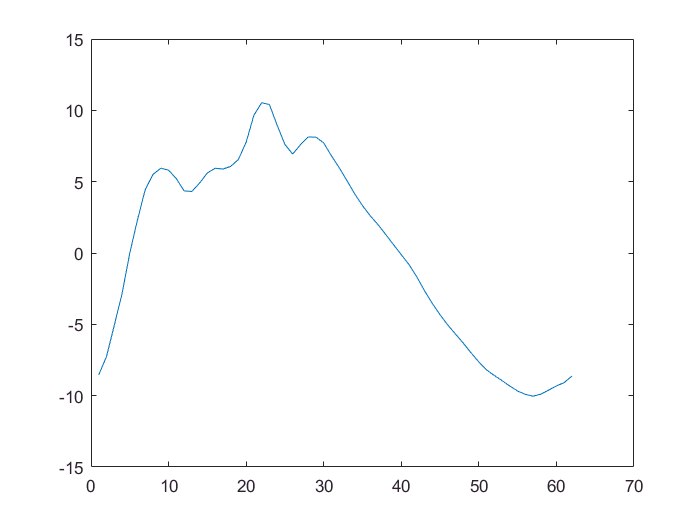

plot(mean(P_anya,2))

P_anya = cell2mat(num2cell(reshape(anya, 62, 13), 1));
P_chas = cell2mat(num2cell(reshape(chas, 80, 10), 1));
P_coli = cell2mat(num2cell(reshape(coli, 80, 10), 1));
P_cusa = cell2mat(num2cell(reshape(cusa, 89, 9), 1));
P_dieg = cell2mat(num2cell(reshape(dieg, 67, 12), 1));
P_jame = cell2mat(num2cell(reshape(jame, 73, 11), 1));
P_juli = cell2mat(num2cell(reshape(juli, 62, 13), 1));
P_kawi = cell2mat(num2cell(reshape(kawi, 62, 13), 1));
P_nate = cell2mat(num2cell(reshape(nate, 62, 13), 1));
P_rick = cell2mat(num2cell(reshape(rick, 67, 12), 1));

V_anya = mean(P_anya,2);
V_chas = mean(P_chas,2);
V_coli = mean(P_coli,2);
V_cusa = mean(P_cusa,2);
V_dieg = mean(P_dieg,2);
V_jame = mean(P_jame,2);
V_juli = mean(P_juli,2);
V_kawi = mean(P_kawi,2);
V_nate = mean(P_nate,2);
V_rick = mean(P_rick,2);

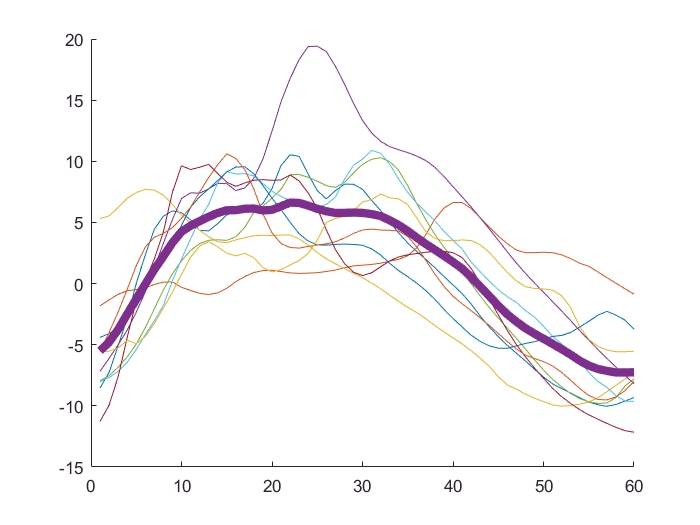

total_avg = (1/10).*(V_anya(1:60)+V_chas(1:60)+V_coli(1:60)+V_cusa(1:60)+V_dieg(1:60)+V_jame(1:60)+V_juli(1:60)+V_kawi(1:60)+V_nate(1:60)+V_rick(1:60));
clf
figure
hold on
plot(V_anya(1:60))
plot(V_chas(1:60))
plot(V_coli(1:60))
plot(V_cusa(1:60))
plot(V_dieg(1:60))
plot(V_jame(1:60))
plot(V_juli(1:60))
plot(V_kawi(1:60))
plot(V_nate(1:60))
plot(V_rick(1:60))
plot(total_avg, 'LineWidth',5)
hold off

N = 60;
Fs = 207;
freqspaceS = linspace(-Fs/2, Fs*(1-1/N)/2, N)

freqspaceS =  -103.5000 -100.0208  -96.5415  -93.0623  -89.5831  -86.1038  -82.6246  -79.1453  -75.6661  -72.1869  -68.7076  -65.2284  -61.7492  -58.2699  -54.7907  -51.3114  -47.8322  -44.3530  -40.8737  -37.3945  -33.9153  -30.4360  -26.9568  -23.4775  -19.9983  -16.5191  -13.0398   -9.5606   -6.0814   -2.6021    0.8771    4.3564    7.8356   11.3148   14.7941   18.2733   21.7525   25.2318   28.7110   32.1903   35.6695   39.1487   42.6280   46.1072   49.5864   53.0657   56.5449   60.0242   63.5034   66.9826


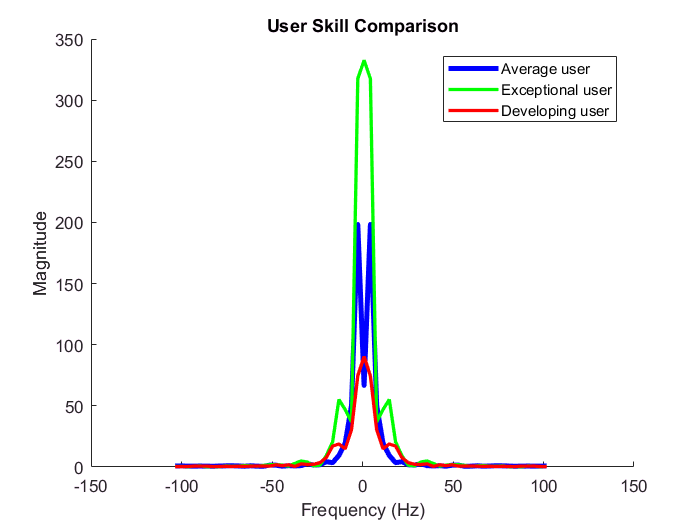

% clf
% plot(freqspaceS, fftshift(abs(fft(V_anya(1:60)))))
% plot(freqspaceS, fftshift(abs(fft(V_chas(1:60)))))
% plot(freqspaceS, fftshift(abs(fft(V_coli(1:60)))))
% plot(freqspaceS, fftshift(abs(fft(V_cusa(1:60)))))
% plot(freqspaceS, fftshift(abs(fft(V_dieg(1:60)))))
% plot(freqspaceS, fftshift(abs(fft(V_jame(1:60)))))
% plot(freqspaceS, fftshift(abs(fft(V_juli(1:60)))))
% plot(freqspaceS, fftshift(abs(fft(V_kawi(1:60)))))
% plot(freqspaceS, fftshift(abs(fft(V_nate(1:60)))))
% plot(freqspaceS, fftshift(abs(fft(V_rick(1:60)))))
% plot(freqspaceS, fftshift(abs(fft(total_avg))))%, 'LineWidth',5)
clf
figure
hold on;
plot(freqspaceS, fftshift(abs(fft(total_avg))),'b','LineWidth',3)
plot(freqspaceS, fftshift(abs(fft(V_cusa(1:60)))),'g','LineWidth',2)
plot(freqspaceS, fftshift(abs(fft(V_chas(1:60)))),'r','LineWidth',2)
title('User Skill Comparison')
xlabel('Frequency (Hz)')
ylabel('Magnitude')
legend({'Average user','Exceptional user','Developing user'},'location','northeast')
hold off;

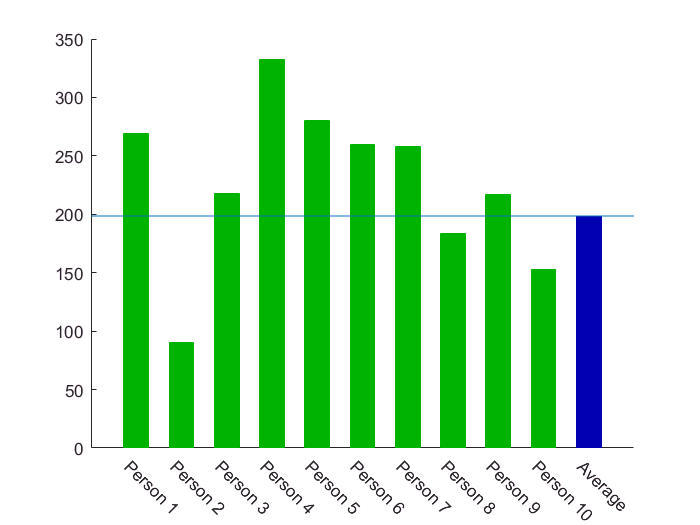

maxs = [max(fftshift(abs(fft(V_anya(1:60))))),max(fftshift(abs(fft(V_chas(1:60))))),max(fftshift(abs(fft(V_coli(1:60))))),max(fftshift(abs(fft(V_cusa(1:60))))),max(fftshift(abs(fft(V_dieg(1:60))))),max(fftshift(abs(fft(V_jame(1:60))))),max(fftshift(abs(fft(V_juli(1:60))))),max(fftshift(abs(fft(V_kawi(1:60))))),max(fftshift(abs(fft(V_nate(1:60))))),max(fftshift(abs(fft(V_rick(1:60))))),max(fftshift(abs(fft(total_avg))))];
subjects = {'Person 1','Person 2','Person 3','Person 4','Person 5','Person 6','Person 7','Person 8','Person 9','Person 10','Average'};

figure
hold on;
bar_graph = bar(maxs(1:10),0.55,'FaceColor',[0 0.7 0],'EdgeColor',[0 0.7 0]);
avg_bar = bar(11,maxs(11),0.55,'FaceColor',[0 0 0.7],'EdgeColor',[0 0 0.7]);
% set(gca,'xticklabel',subjects)
xticks([1,2,3,4,5,6,7,8,9,10,11])
xticklabels(subjects)
xtickangle(-45)
refline([0,maxs(11)])
hold off;

subjects(1)

ans = categorical
     Person 1 
